# Class Activity 7

In this activity, you will develop a simple program that calculates various parameters of a single-stage rocket. The rocket will be launched from a launch pad on the ground at sea-level altitude. 

The forces that act on the rocket during the ascent are demonstrated in Figure (a):

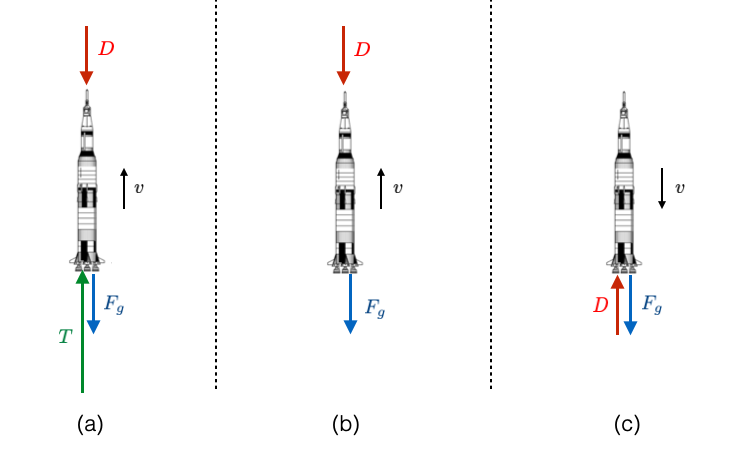

After take-off, the altitude, velocity, and mass of the rocket are subjected to change until the rocket reaches the point of burnout, where all propellant is burned. From this moment forward, the mass of the rocket stays constant, but the velocity and altitude change until the rocket reach its maximum height, a.k.a. apogee. The force acting on the rocket after the burnout is shown in Figure (b). 

At the apogee, the rocket velocity reaches zero momentarily. After apogee, the rocket will start descending, and its speed and altitude will change until it crashes on the ground. Note that during the descent, the drag force acting on the rocket  is in the opposite direction compared to the ascent as shown in Figure (c).

To write the equations of motion for the rocket, we have to represent how each of the 3 variables, altitude $h$, velocity $v$, and mass $m$ is changing with time. We can write these equations as a system of 3 first order differential equations:


$$\frac{dh}{dt} = v(t)$$



$$\frac{dv}{dt} = \frac{T}{m(t)}-\frac{D}{m(t)}-g$$



$$\dot{m}=\frac{dm}{dt} = -\frac{T}{I_{sp} g_0}$$


where $I_{sp}$ is the specific impulse of the rocket engine, and $g_0$ is the gravitational acceleration at sea-level. To be able to find the $v(t)$, $h(t)$, $m(t)$ at any time after the launch, we can use a simple approximation and use an iterative process. This means that we start from $v(t=0)$, $h(t=0)$, and $m(t=0)$ and at the first iteration, we create the value of $v(0+dt)$, $h(0+dt)$, and $m(0+dt)$. 

Then, we continue this for the second iteration using the values from the first iteration. Thus, if we are at iteration $i+1$, we can approximate the 3 variables using the values from the iteration $i$ such that:


$$h(t_i+dt) = h(t_{i+1})=  h(t_i) + v(t_i) \times dt$$



$$v(t_i+dt) = v(t_{i+1}) =  v(t_i)+ \left(\frac{T}{m(t_i)}-\frac{D}{m(t_i)}-g \right) \times dt$$



$$m(t_{i}+dt) = m(t_{i+1}) = m(t_i) - \left(\frac{T}{I_{sp} g_0}\right) \times dt$$


The drag force is a function of the velocity and we can write it as:


$$D(t_{i+1} ) = \left(\frac{1}{2}\rho v^2 \right)AC_D$$


where $\rho$ is the density of air, $A$ is the cross-section area of the rocket, and $C_D$ is the drag coefficient. 

## Part a)

In the first question, we assume that $T$, $C_D$, $g$, $g_0$, and $I_{sp}$ remain constant and are given. Also, the initial value of $m$, $h$, and $v$ are given. 

The mass ratio $n=\frac{m_0}{m_f}$ is the ratio of the initial mass to the final mass of the rocket after burnout. Therefore, the propellant mass can be written as 

Burnout happens when all propellant is burned. 

The objective of your first problem is to write a code that finds the velocity and altitude of a rocket at its burnout. To write the equations of motion in an iterative process, use MATLAB loops (for loop or while loop) to start creating the variables in a recursive process.

Here are the variables that we will use throughout the problem:

% The following variable will be given by the test suites. DO NOT Change them.
% DO NOT overwrite the variables.
g0     = 9.81;                  % ...Sea-level acceleration of gravity (m/s)
diam   = 196.85/12*0.3048;      % ...Vehicle diameter (m)           mf = m0/n
A      = pi/4*(diam)^2;         % ...Frontal area (m^2)
CD     = 0.4;                   % ...Drag coefficient
m0     = 1400;                  % ...Lift-off mass (kg)
n      = 15;                    % ...Mass ratio
T2W    = 1.4;                   % ...Thrust to weight ratio
Isp    = 290;                   % ...Specific impulse (s)
Thrust = T2W*m0*g0;             % ...Rocket thrust (N)

% These variable are constant. DO NOT chnage them or remove them from your code.
g0     = 9.81;                  % ...Sea-level acceleration of gravity (m/s)
Re     = 6378e3;                % ...Radius of the earth (m)
hscale = 7.5e3;                 % ...Density scale height (m)
rho0   = 1.225;                 % ...Sea level density of atmosphere (kg/m^3)
v0     = 0;                     % ...Initial velocity (m/s)
h0     = 0;                     % ...Initial altitude (km)
dt     = 0.001;                 % ...The time increment (s)


Yorr code should start here:

% Find the Propellant mass, and mass flow rate dm/dt. Store the mass flow
% rate in m_dot m_dot = mf; % assign mass flow rate in m_dot
m_dot = Thrust/(Isp*g0); % assign mass flow rate in m_dot
mp = m0*(1-(1/n)); %mass of propellent
totalMass = m0; % total mass equation
h = 0; % equation of height
v = 0; 
Drag = 0;
fprintf("Current Mass = %f", totalMass);

Current Mass = 1400.000000

fprintf("Current Velocity = %f", v0);

Current Velocity = 0.000000

fprintf("Current Height = %f", h0);

Current Height = 0.000000

fprintf("Current Drag = %f", Drag);

Current Drag = 0.000000


% write a loop that continue until you reach the burnout
t=0;
i = 1;
while totalMass(i) > 0
    mp(i) = mp(i) - (m_dot*dt)
    t(i+1) = (t(i) + dt);
    totalMass(i+1) = totalMass(i) - (m_dot*dt); % total mass equation
    v(i+1) = v(i) + ((Thrust/totalMass(i)) - (Drag(i)/totalMass(i)) - g0)*dt; % equation of the velocity
    h(i+1) = (h(i) + v*dt) ; % equation of height
    Drag(i+1) = Drag(i) + (0.5*rho0*v^2*(A*CD));
    i = i+1;
end

mp = 1.3067e+03

Unable to perform assignment because the left and right sides have a different number of elements.




% use dt as the increment of time for each step of your iteration (loop)
% ...Inside the loop, you should have the equations of motion, and you need to 
% ...calculate the drag at each step.
% ...store the velcoty in a vector array v, altitude in a vector array h, and 
% ...mass in vector array m. 





## Part b)

Density, *ρ*, and gravitational acceleration, *g*, both are subjected to change due to the change in altitude. We can write the change in density as:

where  is the density at sea-level, and  is the altitude at iteration *i*, and   is a constant value that is called the "density scale altitude".

The change in gravitational acceleration is given as:

where  is the gravitational acceleration at sea-level and  is the radius of Earth. 

Implement these variables in the equations of motion that you have developed in the previous problem and find the new burnout altitude and velocity.  

## Part c)

In this problem, you should consider the phase of flight after the burnout when the rocket no longer produces a thrust force. However, the rocket will continue ascending to a certain maximum altitude. Your objective in this problem is to continue the loop until you reach this maximum altitude (a.k.a. apogee). The test suite will assess the last element of the h vector. Follow the suggested template and modify your code from the pervious problem. 